clear,clc,close all
import_data_2025MCM_C
medalAmountForSports = readtable("Sport_medal_people2.xlsx");
people2028 = readtable("people2028.xlsx");

tic
never_medal_ind = zeros(3,1);
err_ind = zeros(2,1);
kmedal = 0;
kerr = 0;
knormal = 0;
ktolowevents1 = 0;
ktolowevents2 = 0;
sumallsportimportant1 = struct();
sumallsportimportant2 = struct();
firsttwosport = ["" "" ""; "" "" ""];
predicttable = table();
for n = 1:length(NOC2Country)
    country_temp = NOC2Country(n,1);
    data = medalAmountForSports(string(medalAmountForSports.NOC) == country_temp,:);
    m = max(data.SilverCount);
    data.SilverCount = data.SilverCount/m;
    NumObs = height(data);
    % Reset the random stream state, for reproducibility
    % Comment this line out to generate different data partitions each time the example is run
    rng('default');
    if height(data)<=6
        ktolowevents1 = ktolowevents1 + 1;
        disp(NOC2Country(n,2) + '参加过的项目太少,1')
        continue
    end
    % try
        c = cvpartition(NumObs,'HoldOut',0.4);
        TrainingInd = training(c);
        TestInd = test(c);

        if all(isnan((data.SilverCount)))
            kmedal = kmedal + 1;
            never_medal_ind(kmedal) = n;
            data.SilverCount = zeros(height(data),1);
            % n
            continue
        end

        mdlTobit = fitLGDModel(data(TrainingInd,:),'tobit','CensoringSide','both','PredictorVars',{'sumofpeople' 'Year' 'Sport'},'ResponseVar','SilverCount');
        
        dataSilverCountPredicted = table;
        dataSilverCountPredicted.Observed = data.SilverCount(TestInd) * m;

        dataSilverCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)) * m;
        % disp((dataSilverCountPredicted))

        [~,ind] = sort(mdlTobit.UnderlyingModel.Coefficients.Estimate,'descend');
        % 
        % for m = 1:length(ind)
        %     mdlTobit.UnderlyingModel.CoefficientNames{ind(m)}
        % end
        
        % temp = []

        
        % 判断运动的重要性
        temp = mdlTobit.UnderlyingModel.CoefficientNames;
        if length(temp) <=5
            ktolowevents2 = 0;

            disp(NOC2Country(n,2) + '参加过的项目太少,2')
            continue
        end

        s = [string(temp{ind(1)}),string(temp{ind(2)})];
        indtemp = 2;
        for chachong = 1:4
        while contains("sumofpeople",s)
            for m_temp = 1:2
                if s(m_temp) == "sumofpeople"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("Year",s)
            for m_temp = 1:2
                if s(m_temp) == "Year"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Intercept)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Intercept)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Sigma)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Sigma)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        end
        
        knormal = knormal + 1;
        firsttwosport(knormal,:) = [NOC2Country(n,2) s];
        tc1 = char(s(1));
        tc1(tc1==' ') = '_';
        tc1(tc1=='/') = '_';
        tc1(tc1=='-') = '_';
        ts1 = string(tc1);

        tc2 = char(s(2));
        tc2(tc2==' ') = '_';
        tc2(tc2=='/') = '_';
        tc2(tc2=='-') = '_';
        ts2 = string(tc2);        
        if ismember(tc1,fieldnames(sumallsportimportant1))
            eval("sumallsportimportant1."+ts1+" =  sumallsportimportant1."+ts1+" + 1;");
        else
            eval("sumallsportimportant1."+ts1+" = 1;");
        end
        if ismember(tc2,fieldnames(sumallsportimportant2))
            eval("sumallsportimportant2."+ts2+" =  sumallsportimportant2."+ts2+" + 1;");
        else
            eval("sumallsportimportant2."+ts2+" = 1;");
        end

        %PREDICT 2028
        predict_2028 = people2028(people2028.NOC == country_temp,:);

        total = predict(mdlTobit,predict_2028) * m;
        total(isnan(total)) = 0;
        % sum(total)
        predicttable.NOC(knormal) = country_temp;
        predicttable.country(knormal) = NOC2Country(n,2);
        predicttable.SilverCount(knormal) = sum(total);
        


    % catch ME
    %     kerr = kerr + 1;
    %     err_ind(kerr) = n;
    %     disp(['Iteration ', num2str(n), ': Failed with error - ', ME.message]);
    %     % 可以选择跳过当前迭代或执行其他错误处理逻辑
    % end
    % if mod(n,20) == 0
    %     n
    % end
end

North Yemen参加过的项目太少,1


South Yemen参加过的项目太少,1


Refugee Olympic Athletes参加过的项目太少,1


Crete参加过的项目太少,1


Rhodesia参加过的项目太少,1


Circus参加过的项目太少,1
North Borneo参加过的项目太少,1


Unknown参加过的项目太少,1


Newfoundland参加过的项目太少,1


South Sudan参加过的项目太少,1


% never_medal_ind
toc

历时 18.196193 秒。


firsttwosport

firsttwosport = 137×3 string 数组
    "China"            "Sport_Table Tennis"         "Sport_Gymnastics"      
    "Denmark"          "Sport_Canoe"                "Sport_Art Competitions"
    "Netherlands"      "Sport_Cycling"              "Sport_Equestrian"      
    "Finland"          "Sport_Wrestling"            "Sport_Archery"         
    "Norway"           "Sport_Figure Skating"       "Sport_Shooting"        
    "Romania"          "Sport_Equestrian"           "Sport_Gymnastics"      
    "Estonia"          "Sport_Boxing"               "Sport_Weightlifting"   
    "France"           "Sport_Croquet"              "Sport_Breaking"        
    "Morocco"          "Sport_Athletics"            "Sport_Rowing"          
    "Spain"            "Sport_Polo"                 "Sport_Karate"          
    "Egypt"            "Sport_Modern Pentathlon"    "Sport_Wrestling"       
    "Iran"             "Sport_Taekwondo"            "Sport_Weightlifting"   
    "Bulgaria"         "Sport_Volleyball"   

predicttable

predicttable = 137×3 table
     NOC        country       SilverCount
    _____    _____________    ___________

    "CHN"    "China"            37.786   
    "DEN"    "Denmark"          1.8579   
    "NED"    "Netherlands"      8.6156   
    "FIN"    "Finland"          0.6579   
    "NOR"    "Norway"           2.2329   
    "ROU"    "Romania"          4.1181   
    "EST"    "Estonia"               0   
    "FRA"    "France"           15.283   
    "MAR"    "Morocco"               0   
    "ESP"    "Spain"            8.3172   
    "EGY"    "Egypt"                 0   
    "IRI"    "Iran"              2.935   
    "BUL"    "Bulgaria"         5.8497   
    "ITA"    "Italy"            14.091   
    "AZE"    "Azerbaijan"       2.7001   
    "SUD"    "Sudan"                 0   


% disp((dataSilverCountPredicted))

sumallsportimportant1

sumallsportimportant1 = 包含以下字段的 struct :
             Sport_Table_Tennis: 6
                    Sport_Canoe: 10
                  Sport_Cycling: 5
                Sport_Wrestling: 5
           Sport_Figure_Skating: 2
               Sport_Equestrian: 2
                   Sport_Boxing: 11
                  Sport_Croquet: 1
                Sport_Athletics: 14
                     Sport_Polo: 2
        Sport_Modern_Pentathlon: 1
                Sport_Taekwondo: 8
               Sport_Volleyball: 7
                  Sport_Fencing: 5
                   Sport_Karate: 5
                     Sport_Judo: 3
                   Sport_Tennis: 2
            Sport_Weightlifting: 7
                  Sport_Sailing: 3
                   Sport_Hockey: 2
                 Sport_Football: 2
                  Sport_Archery: 8
                Sport_Badminton: 5
                  Sport_Surfing: 1
                Sport_Triathlon: 3
         Sport_Art_Competitions: 2
    Sport_Baseball_and_Softball: 1
           

sumallsportimportant2

sumallsportimportant2 = 包含以下字段的 struct :
           Sport_Gymnastics: 9
     Sport_Art_Competitions: 3
           Sport_Equestrian: 3
              Sport_Archery: 4
             Sport_Shooting: 10
        Sport_Weightlifting: 12
             Sport_Breaking: 1
               Sport_Rowing: 6
               Sport_Karate: 1
            Sport_Wrestling: 11
           Sport_Volleyball: 4
                Sport_Canoe: 5
            Sport_Athletics: 7
              Sport_Sailing: 5
                 Sport_Judo: 7
           Sport_Tug_Of_War: 1
               Sport_Boxing: 13
            Sport_Badminton: 2
              Sport_Cycling: 6
                 Sport_Golf: 1
              Sport_Surfing: 1
              Sport_Fencing: 4
             Sport_Football: 4
           Sport_Basketball: 2
       Sport_Sport_Climbing: 1
                Sport_Rugby: 1
         Sport_Table_Tennis: 2
            Sport_Taekwondo: 6
    Sport_Modern_Pentathlon: 1
            Sport_Triathlon: 1
               Sport_Tenn



% people2028.Year = 2028 * ones(height(people2028),1)
% dataSilverCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)); %%%预测用！！！

[~,ind] = sort(predicttable.SilverCount,'descend');
predicttable = predicttable(ind,:)

predicttable = 137×3 table
     NOC         country        SilverCount
    _____    _______________    ___________

    "GDR"    "East Germany"        135.4   
    "URS"    "Soviet Union"       62.325   
    "USA"    "United States"       44.92   
    "FRG"    "West Germany"       42.535   
    "CHN"    "China"              37.786   
    "RUS"    "Russia"               33.4   
    "AUS"    "Australia"          21.601   
    "BRA"    "Brazil"             21.591   
    "JPN"    "Japan"              21.256   
    "FRA"    "France"             15.283   
    "GER"    "Germany"            14.165   
    "ITA"    "Italy"              14.091   
    "GBR"    "Great Britain"      13.889   
    "PER"    "Peru"               11.719   
    "EUN"    "Unified Team"       10.969   
    "ROC"    "Russia"             9.0002   


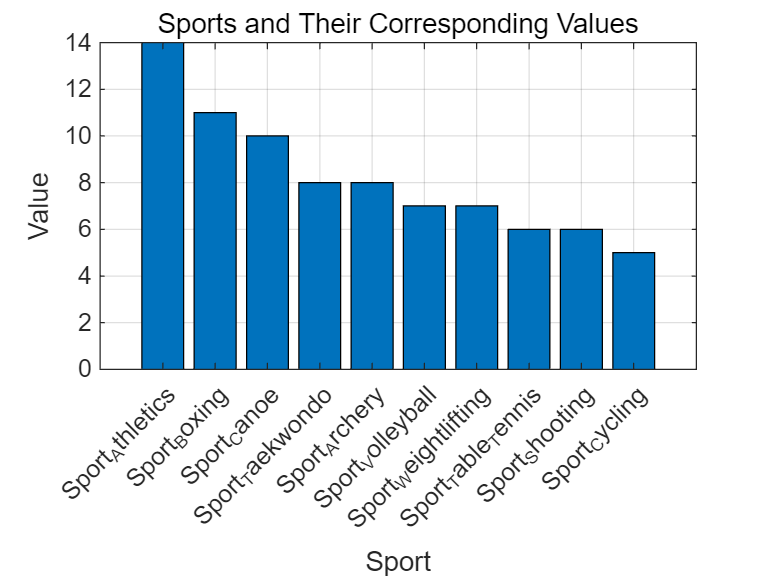

% ind_change = [1 2 5 14 22 85 112 117 139]
% 
% 
% % predicttable(1:155~=ind_change,:)
% predicttable([3,4,6:13],:)

% 假设你的结构体名为 sumallsportimportant1
sports = string(fieldnames(sumallsportimportant1)); % 获取结构体字段名（运动项目）
values = struct2array(sumallsportimportant1); % 将结构体转换为数组（对应的数值）
[values,ind] = sort(values,'descend');
sports = sports(ind(1:10));
values = values(1:10);
% 注意：struct2array 默认返回结构体中第一个字段的数组，如果所有字段都是相同大小的数值数组，这可以工作。
% 但如果结构体中有非数值字段或字段大小不一致，这种方法会出错。
% 在这个例子中，我们假设所有字段都是数值且大小相同（即只有一个数值）。
 
% 如果 struct2array 不适用（例如，如果结构体中有混合类型的数据），你需要手动提取数值：
% values = zeros(1, length(sports));
% for i = 1:length(sports)
%     values(i) = sumallsportimportant1.(sports{i});
% end
 
% 绘制条形图
figure; % 创建新图形窗口
bar(values); % 绘制条形图（默认 x 轴是索引）
 
% 设置 x 轴标签为运动项目名称
set(gca, 'XTickLabel', sports); % gca 获取当前轴句柄
% xstickrotation(45); % 旋转 x 轴标签，以便更好地显示长名称
 xtickangle(45);
% 设置图表标题和轴标签
title('Sports and Their Corresponding Values');
xlabel('Sport');
ylabel('Value');
 
% 如果需要，还可以添加网格线、图例等
grid on;

% % 假设你的结构体名为 sumallsportimportant1
% sports = string(fieldnames(sumallsportimportant2)); % 获取结构体字段名（运动项目）
% values = struct2array(sumallsportimportant2); % 将结构体转换为数组（对应的数值）
% [values,ind] = sort(values,'descend');
% sports = sports(ind(1:10));
% values = values(1:10);
% 
% % 注意：struct2array 默认返回结构体中第一个字段的数组，如果所有字段都是相同大小的数值数组，这可以工作。
% % 但如果结构体中有非数值字段或字段大小不一致，这种方法会出错。
% % 在这个例子中，我们假设所有字段都是数值且大小相同（即只有一个数值）。
% 
% % 如果 struct2array 不适用（例如，如果结构体中有混合类型的数据），你需要手动提取数值：
% % values = zeros(1, length(sports));
% % for i = 1:length(sports)
% %     values(i) = sumallsportimportant1.(sports{i});
% % end
% 
% % 绘制条形图
% figure; % 创建新图形窗口
% bar(values); % 绘制条形图（默认 x 轴是索引）
% 
% % 设置 x 轴标签为运动项目名称
% set(gca, 'XTickLabel', sports); % gca 获取当前轴句柄
% % xstickrotation(45); % 旋转 x 轴标签，以便更好地显示长名称
%  xtickangle(45);
% % 设置图表标题和轴标签
% title('Sports and Their Corresponding Values');
% xlabel('Sport');
% ylabel('Value');
% 
% % 如果需要，还可以添加网格线、图例等
% grid on;